m = 10;
g = 9.8;
b = 1;
w_max = 20; % ограничение частоты вращения
u_max = b*w_max^2;
[z, z_diff] = z_solve(); % представление z и z' в виде функций 
                         % с помощью символьного решения
u = @(t, kd, kp, m, z_star) min(kp * (z(t, kd, kp, m, z_star) - z_star) ...
+ kd * z_diff(t, kd, kp, m, z_star) + m * g, u_max);
fun = @(t, kd_kp, m, z_star) ((z(t, kd_kp(1), kd_kp(2), m, z_star) - z_star) ^ 2) ...
    + z_diff(t, kd_kp(1), kd_kp(2), m, z_star)^2 ... 
    + u(t, kd_kp(1), kd_kp(2), m, z_star)^2; % подинтегральная функция
I = @(kd_kp, z_star) integral(@(t) fun(t, kd_kp, m, z_star), ...
                                    0, 50, 'ArrayValued', true);

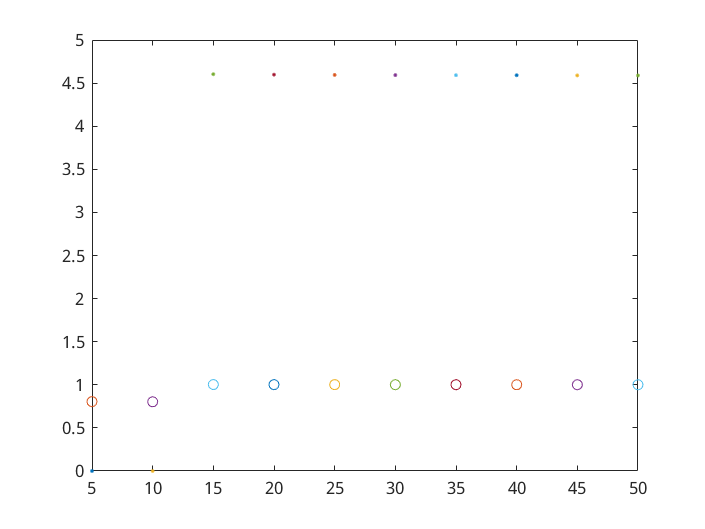

z_star_list = linspace(5, 50, 10);
for i = 1:length(z_star_list)
    z_star = z_star_list(i);
    optimized_vector = fminsearch(@(v) I(abs(v), z_star), [1, 1]); % kd, kp >= 0
    plot(z_star, optimized_vector(1), '.', z_star, optimized_vector(2), 'o'); hold on
end